Aristotle University of Thessaloniki (AUTh)

Department of Electrical and Computer Engineering

Ioannis Deirmentzoglou AEM: 10015 Email: deirmentz@ece.auth.gr

The present livescript contains the code and the output results for the Linear PI controller that controls the mechanism of angular velocity of work table 

Root Locus analysis for the open loop transfer function:

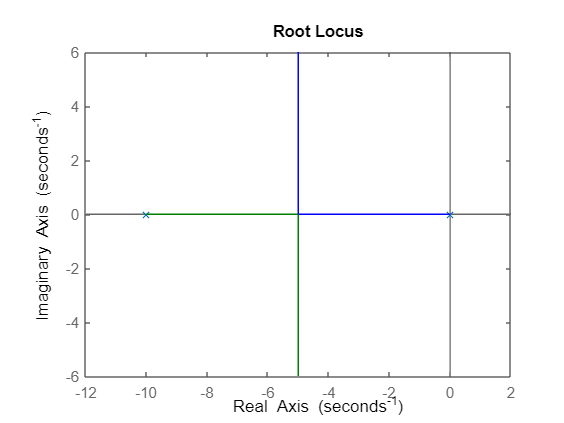

% Root Locus analysis for the open loop transfer function
% Parameter of gain Ka of the amplifier is considered to be 1 

% Open loop transfer function 
K = 25;   % Gain K value
c = 0.1;  % Zero c value

A_s = tf([K], [1 10 0]);
rlocus(A_s);

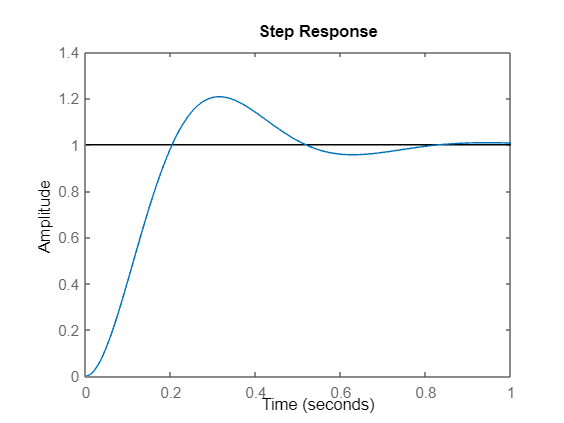


% Step response for the closed loop transfer function, 
% after the calculation of the gain Kp 
% Open loop transfer function for Kp = 2.5
Kp = 2.5 ;
A_s = tf([Kp*K], [1 10 0]);

% Closed loop transfer function for Kp = 2.5
H_s = feedback(A_s, 1, -1);

% Step response for the closed loop transfer function
figure;
step(H_s);


% Info about the step response
S = stepinfo(H_s);

% Print the results about rise time and overshoot 
fprintf('Step Respose Results');

Step Respose Results

fprintf('Rise time(sec): %f', S.RiseTime);

Rise time(sec): 0.138069

fprintf('Overshoot(%%): %f', S.Overshoot);

Overshoot(%): 20.786634